**ICAE-03 (IT 3143 - P)**

**Registation number :- 2019/ICT/72**

01. Consider the images cameraman.jpg and rice.png.

a. Read and show the original images. 

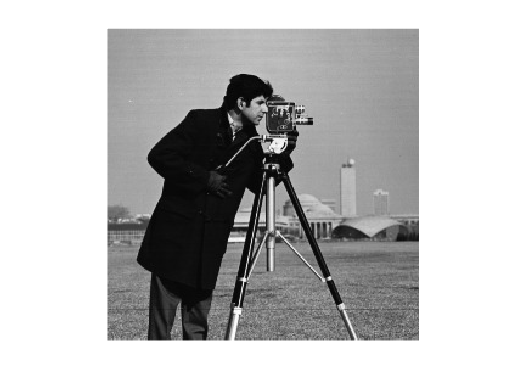

image1=imread('cameraman.jpg');
image2=imread('rice.png');

%show the image
subplot(2,2,1)=imshow(image1);

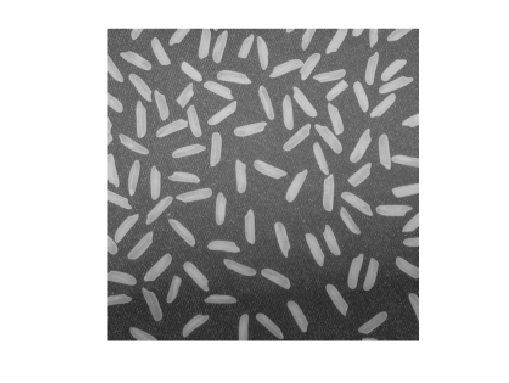

subplot(2,2,2)=imshow(image2);

b. Write cameraman.jpg as cameraman.png. (Use Matlab function imwrite)

imwrite(image1,'cameraman.png','png');
image1new=imread('cameraman.png');

c. Add them to make a single image and display the result. (Use Matlab function imadd)

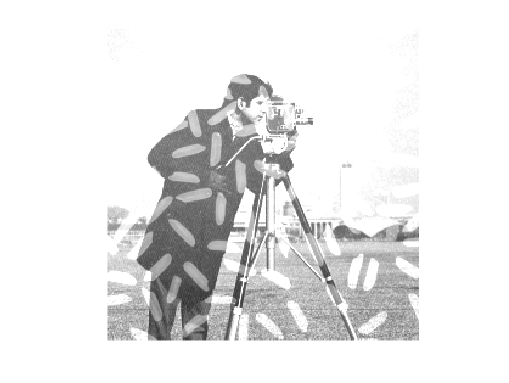

mixImage=imadd(image1new,image2);

%show the image
imshow(mixImage);

e. Using the function defined in d, display the result for the images cameraman.png and rice.png. 

AddTwoImages(image1new,image2); %result of the cameraman.png and rice.png

f. Write a code to find all pixels for which the rice image has a value less than that of the cameraman image and copy the corresponding pixel values into the cameraman image. And display the result. 

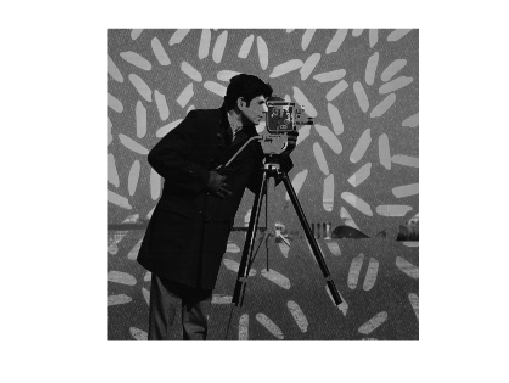

pixelReplace=image1new>image2;
image1new(pixelReplace)=image2(pixelReplace);
imshow(image1new);

g. Reflect the rice image about the x-axis, and the cameraman image about the y-axis. Then, add them together and display the result using the function AddTwoImages.

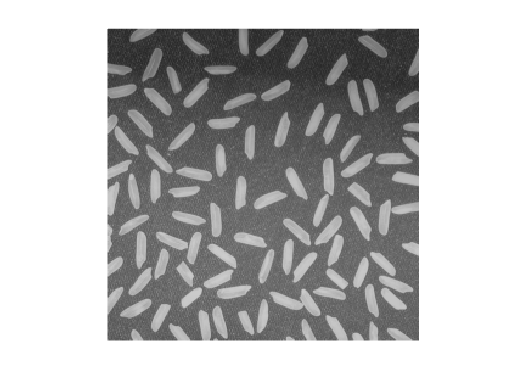

%reflect of rice image to x-axis
reflectx=flipud(image2);
imshow(reflectx);

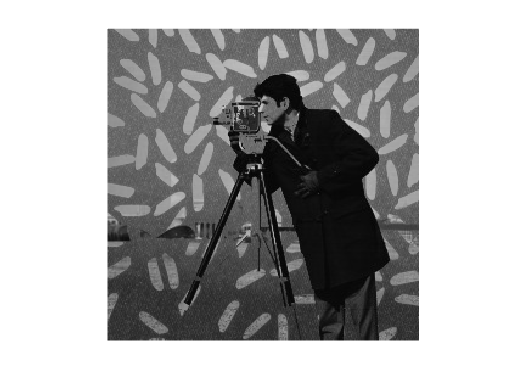


%reflect of cameraman image to y-axis
reflecty=fliplr(image1new);
imshow(reflecty);

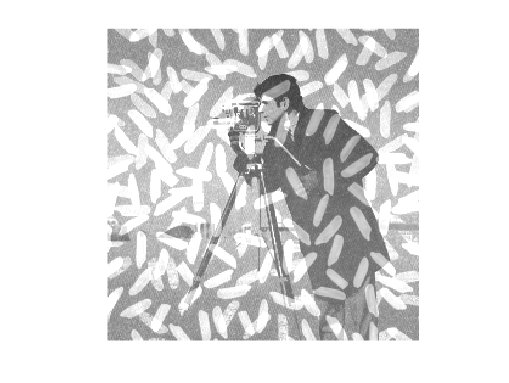


%use the AddTwoImages fuction to add the 2 images
imageReflect=AddTwoImages(reflectx,reflecty);

imshow(imageReflect);

02. Consider the image shape.png. Using the morphological operations find the following outputs eroded image, dilated image, open image and close image. Also find the border of the shapes. (use the 15 ×15 square structuring element).

ans =   handle to deleted Graphics


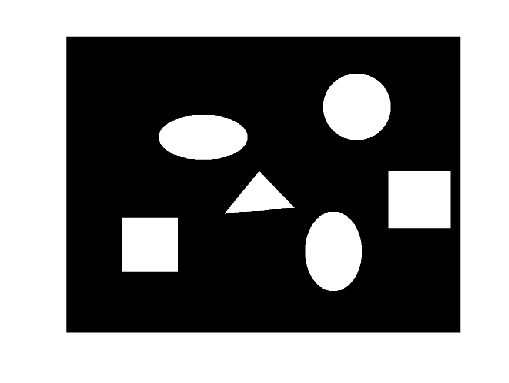

image3=imread('Shape.png');
shape=strel('square',15);
subplot(2,2,1),imshow(image3);

ans =   handle to deleted Graphics


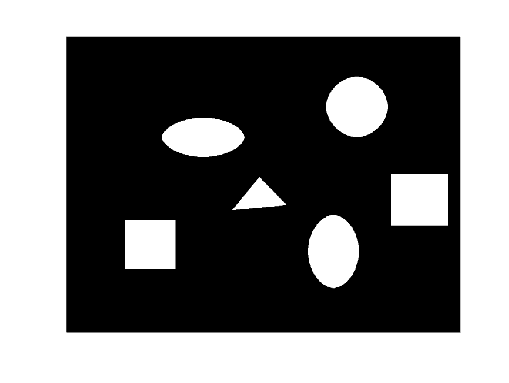


%eroded image
erode=imerode(image3,shape);
subplot(2,2,2),imshow(erode);

ans =   handle to deleted Graphics


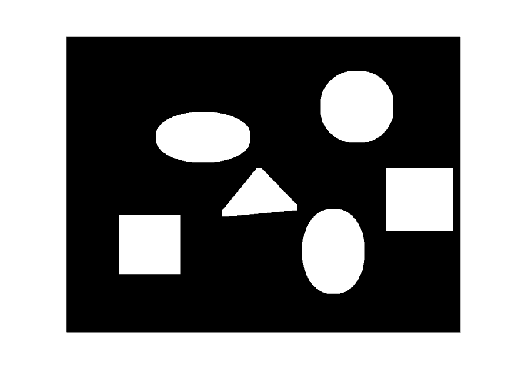


%dilated image
dilated=imdilate(image3,shape);
subplot(2,2,1),imshow(dilated);

ans =   handle to deleted Graphics


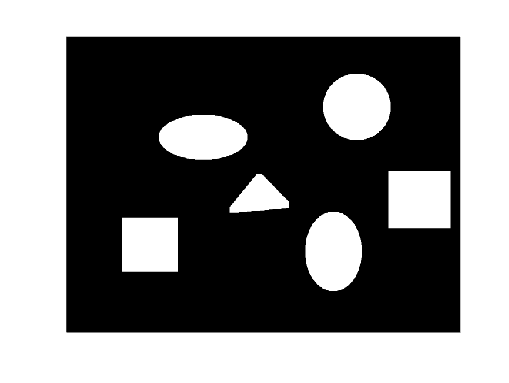


%open image
open=imopen(image3,shape);
subplot(2,2,2),imshow(open);

ans =   handle to deleted Graphics



%close image
close=imclose(image3,shape);
subplot(2,2,1),imshow(close);

ans =   handle to deleted Graphics


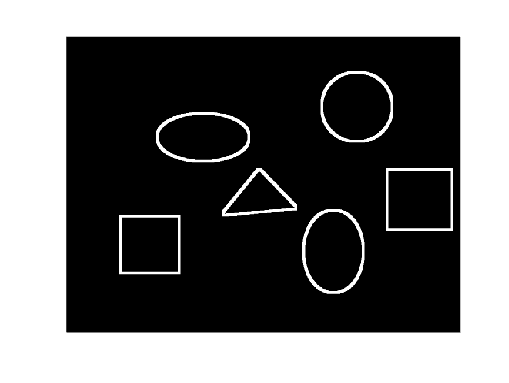


%border image
border=imdilate(image3,shape)-image3;
subplot(2,2,2),imshow(border);

d. Define a function AddTwoImages that has two images as parameters to add two images together (without using any predefined Matlab function), and displays the resultant image.

function addImage=AddTwoImages(img1,img2) %function to add 2 images
    addImage=img1+img2;
    imshow(addImage);
end